resultthree = "resultthree/";
resultmitsuba = "resultmitsuba/";
ana_result = "analysisresult/";

% 事前に定義された行列と対応する行名と列名
rowNames = {'cu_0.025', 'cu_0.129', 'pla_0.075', 'pla_0.225'};
rowNames2 = {'cu-0.025', 'cu-0.129', 'pla-0.075', 'pla-0.225'};
colNames = [19, 39, 78, 80, 102, 125, 152, 203, 226, 227, 230, 232, 243, 278, 281];

%-----------------------------------
% three parts
%-----------------------------------
threedataMatrix = zeros(4, 15);

% Excelファイル名
dirInfo = dir(resultthree);
filesNames = {dirInfo(~ismember({dirInfo(:).name}, {'.', '..'})).name};
numFiles = sum(~ismember({dirInfo(:).name}, {'.', '..'}));
filename = fullfile(resultthree, filesNames{1});
disp(filename);

resultthree\kawahara_three.xlsx



for foldernum =1:numFiles
    for materialnum = 1:length(rowNames)
        sheetName = rowNames{materialnum};
        sheetData = readtable(filename, 'Sheet', sheetName, 'ReadVariableNames', false);
        
        names = sheetData{:, 1};
        scores = sheetData{:, 2};
        
        for i = 1:length(names)
            nameStr = names{i};
            idStr = regexp(nameStr, '\d+', 'match');
            idNum = str2double(idStr(end));
            colIndex = find(colNames == idNum);
            rowIndex = find(strcmp(rowNames, sheetName));
            if ~isempty(colIndex) && ~isempty(rowIndex)
                threedataMatrix(rowIndex, colIndex) = threedataMatrix(rowIndex, colIndex) + scores(i);
            end
        end
    end
end

disp(threedataMatrix);

  1 列から 12 列

   -0.4011    0.5724    0.5724   -0.8014    0.6292    1.2025    0.5724    1.2593   -1.2016   -1.4883    0.9159    2.2896
   -0.5495    0.1374    0.8243    0.4808   -0.2061    1.1677    1.2566    1.5112   -1.2364   -0.5495   -0.5495    1.5112
   -1.2305    0.0687   -0.9616    0.8124    0.4690    1.4425    0.0687   -0.3316   -1.3797   -1.6485    1.0990    1.7859
   -1.2469   -0.1832   -0.4698    0.5037    1.1906    0.5037    0.5037    1.1906   -1.8670   -1.1246   -0.1832    0.9218

  13 列から 15 列

    0.2290   -2.5186   -1.8317
    0.7354   -2.6102   -1.9233
    1.0422   -2.3354    1.0990
    0.7725   -0.3289   -0.1832




%-----------------------------------
% mitusba parts
%-----------------------------------
mitsubadataMatrix = zeros(4, 15);

% Excelファイル名
dirInfo = dir(resultmitsuba);
filesNames = {dirInfo(~ismember({dirInfo(:).name}, {'.', '..'})).name};
numFiles = sum(~ismember({dirInfo(:).name}, {'.', '..'}));
filename = fullfile(resultmitsuba, filesNames{1});
disp(filename);

resultmitsuba\kawahara_mitsuba.xlsx



for foldernum =1:numFiles
    for materialnum = 1:length(rowNames)
        sheetName = rowNames{materialnum};
        sheetData = readtable(filename, 'Sheet', sheetName, 'ReadVariableNames', false);
        
        names = sheetData{:, 1};
        scores = sheetData{:, 2};
        
        for i = 1:length(names)
            nameStr = names{i};
            idStr = regexp(nameStr, '\d+', 'match');
            idNum = str2double(idStr(end));
            colIndex = find(colNames == idNum);
            rowIndex = find(strcmp(rowNames, sheetName));
            if ~isempty(colIndex) && ~isempty(rowIndex)
                mitsubadataMatrix(rowIndex, colIndex) = mitsubadataMatrix(rowIndex, colIndex) + scores(i);
            end
        end
    end
end

disp(mitsubadataMatrix);

  1 列から 12 列

   -0.1603    0.8701    0.1832    0.1832    0.8701    0.6538    1.5569    1.5569   -2.2209   -0.9040   -0.8472    1.5569
   -0.1576   -0.0687   -0.7556    0.2748    0.3636    0.9616    0.9616    1.3619   -2.0021   -1.0990    0.6182    1.9352
   -1.1448    0.2290   -0.8014    0.2290    0.5156    1.6027    0.5724    1.1485   -1.7428    0.2290    0.2858    1.3701
   -0.7785    0.5385   -1.4654    1.2822   -0.4350   -0.0916   -0.7785    1.2822   -2.1522   -0.0348    0.2519    0.3407

  13 列から 15 列

    0.3994   -2.2209   -1.4772
    0.9616   -2.2566   -1.0990
    0.9159   -2.2640   -1.1448
    1.2822    0.5953    0.1630



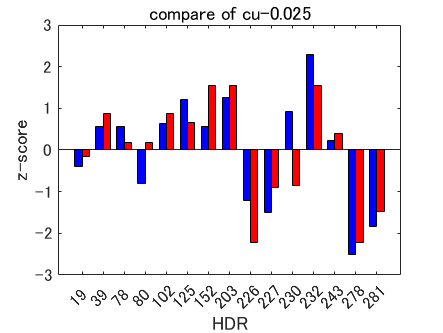

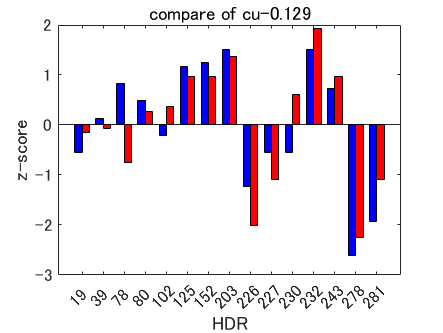

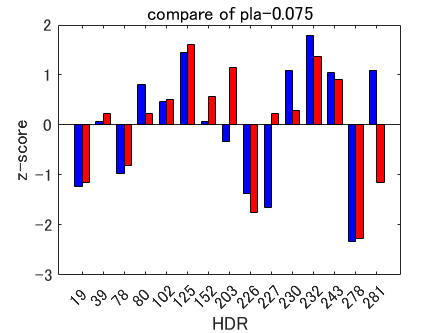

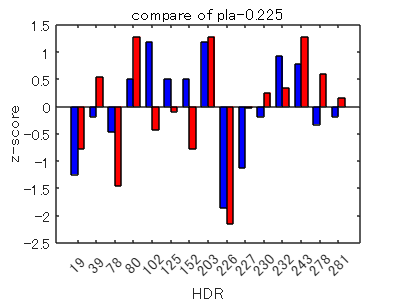

%-----------------------------------
% analysis
%-----------------------------------
%bar graph
for row = 1:4
    figure;
    bar_width = 0.35;
    x = 1:length(colNames);

    % threedataのプロット
    bar(x - bar_width/2, threedataMatrix(row, :), bar_width, 'FaceColor', 'b', 'DisplayName', 'three'); 
    hold on;
    
    % mitsubadataのプロット
    bar(x + bar_width/2, mitsubadataMatrix(row, :), bar_width, 'FaceColor', 'r', 'DisplayName', 'mitsuba'); 
    
    set(gca, 'XTick', 1:length(colNames));
    set(gca, 'XTickLabel', colNames);
    xlabel('HDR'); 
    ylabel('z-score');
    title(['compare of ' rowNames2{row}]);
    %legend('show');
end


%correlation_coefficients
correlation_coefficients = zeros(1, 4);
for row = 1:4
    data_three = threedataMatrix(row, :);
    data_mitsuba = mitsubadataMatrix(row, :);
    corr_matrix = corrcoef(data_three, data_mitsuba);
    correlation_coefficients(row) = corr_matrix(1, 2);
end

disp(correlation_coefficients);

    0.8340    0.8492    0.7006    0.6132

